# Complex Exponential(CE) system identification algorithm.

The algorithm that we'll implement, is called the "**Complex Exponential method**" (CE) or as it is sometimes known "**Prony's method**" ... and it can be used to characterize(identify) the natural modes of vibration of a mechanical/aerospace structure.  

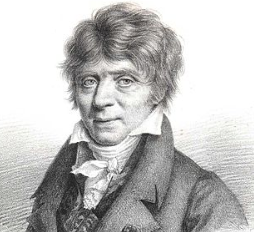 Gaspard Riche de Prony (REF: [https://en.wikipedia.org/wiki/Gaspard_de_Prony](https://en.wikipedia.org/wiki/Gaspard_de_Prony) )

# **Function INPUTS :**

- `frf_col    : our measured FRF (` **ATTENTION:**  `it `**must**` be the conjugate symmetric full FRF)`

- `fhz_col    : the frequencies(Hz) of our measured FRF`

- `Num_modes  : Number of modes in the FRF sum`

- `dt         : sampling time (seconds)`

# **Function OUTPUTS :**

- `w_rads     : our identified natural frequncies (rad/sec)`

- `damp_ratio : our identified damping ratios  (-)`

# **Example usage:**

- see the script file **DEMO_for_CE_algorithm_with_SGtbx.mlx**

# **Background:**

The **Transfer Function** of a mechanical structure can be represented by the following parametric equation:

- $\;H\left(s\right)=\;\;\left(\sum_{r=1}^N \left.\;\;\;\frac{R_r }{s-\lambda_r }\;\;\;+\;\;\;\;\frac{\bar{R_r } }{s-\bar{\lambda_r } }\right)\;\;\right.$                                `----- (Eq_01)`

where:

- $R_r$    =  a complex residue(or shape factor) for mode r

- $\lambda_r$    = $-\zeta_r \ldotp \omega_{\mathrm{n}r} \;+i\ldotp \omega_{\mathrm{n}r} \ldotp \sqrt{1-\;\zeta_r^2 }$   = system POLE for mode r

- $\omega_{\mathrm{n}r}$  = UN damped modal frequency (rad/sec) for mode r

- $\zeta_r$     = damping ratio for mode r

- $\bar{R}$      = complex conjugate of R

- $\bar{\lambda}$       = complex conjugate of $\lambda$

Equation `Eq_01` can also be written as:

- $H\left(s\right)=\;\;\left(\sum_{r=1}^{2N} \left.\;\;\;\frac{R_r }{s-\lambda_r }\;\;\right)\;\;\right.$               `----- (Eq_02)`      where:  for (r>N) we have $R_r =\bar{R_r }$and $\lambda_r =\bar{\lambda_r }$ 

Now if we take the inverse Laplace transform of (`Eq_02`), we get:

- $h\left(t\right)=\left(\;\sum_{r=1}^{2N} \;\;R_r \;\ldotp e^{\lambda_r \ldotp t} \;\;\;\right)$                     `----- (Eq_03)` 

- where $h\left(t\right)$ is referred to as the ***Impulse Response Function*** (IRF)

In this algorithm we will determine:

- $\omega_{\mathrm{n}r}$    :   `our identified natural frequencies (rad/sec)`

- $\zeta_r$      :   `our identified damping ratios  (-)`

`Bradley Horton, bhorton@mathworks.com`

function [w_rads, damp_ratio] = bh_our_custom_CE_alg(frf_col, fhz_col, Num_modes, dt)
    arguments
      frf_col   (:,1)   {mustBeNumeric}
      fhz_col   (:,1)   {mustBeNumeric}
      Num_modes (1,1)   {mustBeNumeric, mustBePositive, mustBeInteger}
      dt        (1,1)   {mustBeNumeric, mustBePositive}
    end

## `Function INPUTS :`

- `frf_col    : our measured FRF (` **ATTENTION:**  `it `**must**` be the conjugate symmetric full FRF) `

- `fhz_col    : the frequencies(Hz) of our measured FRF`

- `Num_modes  : Number of modes in the FRF sum`

- `dt         : sampling time (seconds)`

## `Function OUTPUTS :`

- `w_rads     : our identified natural frequencies (rad/sec)`

- `damp_ratio : our identified damping ratios  (-)`

##  Please NOTE

- `The FRF `**must**` be the conjugate symmetric full FRF`

### Step_0:  Convert the measured FRF into an IRF

Convert a measured , sampled (sample time is $\Delta \;$seconds) and **conjugate symmetric FRF** into it's corresponding measured **Impulse Response Function (IRF**).

- See the local SUBfunction `LOC_cal_meas_IRF()`  

THE_IRF = LOC_cal_meas_IRF(frf_col, dt);

### STEPS 1 to 5: 

Recall the analytical expression for our IRF:

- 
$$h\left(t\right)\;\;\;=\;\;\sum_{r=1}^{2N} \;\;R_r \;\ldotp e^{\lambda_r \ldotp t} \;\;\;$$
 

Now we can "relate" our measured IRF to the analytic expression for the IRF, via the following:

- 
$$h\left(k\ldotp \Delta \right)=\sum_{r=1}^{2N} \;\;R_r \;\ldotp e^{\lambda_r \ldotp k\ldotp \Delta } \;\;\;$$


- 
$$h_k =\sum_{r=1}^{2N} \;\;R_r \;\ldotp e^{\lambda_r \ldotp k\ldotp \Delta } \;\;\;$$


- $h_k =\sum_{r=1}^{2N} \;\;R_r \;\ldotp Z_r^k \;\;\;$                   `----- (Eq_04)`       where   $Z_r^k =e^{\lambda_r \ldotp k\ldotp \Delta }$   and   $Z_r =e^{\lambda_r \ldotp \Delta }$

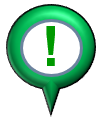 Behold **Prony's** trick:

Now because $Z_r$ occurs in complex conjugate pairs, we know there must be a polynomial $y=f\left(Z\right)$ of order 2N with real coefficients $\beta_k$ whose ROOTS are $Z_r$ ie:

- $\beta_0 \;\;+\;\;\;\beta_1 \ldotp Z_r \;\;+\;\;\;\beta_2 \ldotp Z_r^2 \;\;\;+\;\;\beta_3 \ldotp Z_r^3 \;\;\;+\;\;\ldotp \ldotp \ldotp \;+\;\;\;\beta_{2N-1} \ldotp Z_r^{2N-1} \;\;\;\;+\;\;\;\;\beta_{2N} \ldotp Z_r^{2N} \;\;\;=\;\;0$    `----- (Eq_05)`

And we can write `(Eq_05)` as:

- $0\;=\;\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp Z_r^k \;\;\;$                `----- (Eq_06)`

Because we can, let's play with $\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp h_{k+p} \;\;$and see what happens.  We will utilize `Eq_04 `and `Eq_05`

- $\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp h_{k+p} \;\;$ =    $\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp \left(h_{k+p} \right)\;\;$ =    $\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp \left(\sum_{r=1}^{2N} \;\;R_r \;\ldotp Z_r^{k+p} \;\;\;\right)\;$=   $\sum_{r=1}^{2N} \;\;R_r \;\ldotp Z_r^p \;\ldotp \left(\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp Z_r^k \;\;\;\right)\;$

So invoking `(Eq_06)` we can write:

- $\sum_{k=0}^{2N} \;\;\beta_k \;\ldotp h_{k+p} \;\;$ =  0              `----- (Eq_06)`

So if we choose $\bf{\beta_{2N}==1}$ we can write:

-   
$$\left\lbrack \begin{array}{ccccc}
h_0  & h_1  & h_2  & \cdots  & h_{2N-1} \\
h_1  & h_2  & h_3  & \cdots  & h_{2N} \\
h_2  & h_3  & h_4  & \cdots  & h_{2N+1} \\
h_3  & h_4  & h_5  & \cdots  & h_{2N+2} \\
\vdots  & \vdots  & \vdots  &  & \vdots \\
 &  &  &  & 
\end{array}\right\rbrack \;\ldotp \left\lbrack \begin{array}{c}
\beta_0 \\
\beta_1 \\
\vdots \\
\beta_{2N-1} 
\end{array}\right\rbrack \;\;=\;\;\;\;\;-1\times \left\lbrack \begin{array}{c}
h_{2N} \\
h_{2N+1} \\
h_{2N+2} \\
h_{2N+3} \\
\vdots \\

\end{array}\right\rbrack$$


%  assemble the HANKEL matrix.     TIP:  >> doc hankel
%max_pts = round( length(THE_IRF)/3 );
%max_pts = round( length(THE_IRF)*0.95 );
max_pts = round( length(THE_IRF)*0.5 );
irf     = THE_IRF(1:max_pts);
irfp    = THE_IRF(1:(1 + max_pts));

Nc      = 2*Num_modes; 
Np      = numel(irf);
Nr      = (Np+1) - Nc;

H_mat = zeros(Nr, Nc);
for rr=1:Nr
    ind            = [rr:(rr-1+Nc)];
    some_chunk_row = [irf(ind)]';
    H_mat(rr,:)    = some_chunk_row;
end

m_col        = -irf((2*Num_modes + 1):end);
m_col(end+1) = -irfp(end);

Now solve the matrix equation:    $H\ldotp \beta =m$

- 
$$\left\lbrack \begin{array}{ccccc}
h_0  & h_1  & h_2  & \cdots  & h_{2N-1} \\
h_1  & h_2  & h_3  & \cdots  & h_{2N} \\
h_2  & h_3  & h_4  & \cdots  & h_{2N+1} \\
h_3  & h_4  & h_5  & \cdots  & h_{2N+2} \\
\vdots  & \vdots  & \vdots  &  & \vdots \\
 &  &  &  & 
\end{array}\right\rbrack \;\ldotp \left\lbrack \begin{array}{c}
\beta_0 \\
\beta_1 \\
\vdots \\
\beta_{2N-1} 
\end{array}\right\rbrack \;\;=\;\;\;\;\;-1\times \left\lbrack \begin{array}{c}
h_{2N} \\
h_{2N+1} \\
h_{2N+2} \\
h_{2N+3} \\
\vdots \\

\end{array}\right\rbrack$$


beta_col = H_mat \ m_col; 

### Step 09:

Once we know what $\beta_k$ is, then we can revisit the "Prony's trick" polynomial and solve for the roots (remember that $\bf{\beta_{2N}==1}$), ie:

-  
$$\beta_0 \;\;+\;\;\;\beta_1 \ldotp Z_r \;\;+\;\;\;\beta_2 \ldotp Z_r^2 \;\;\;+\;\;\beta_3 \ldotp Z_r^3 \;\;\;+\;\;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \;+\;\;\;\beta_{2N-1} \ldotp Z_r^{2N-1} \;\;\;\;+\;\;\;\;1\ldotp Z_r^{2N} \;\;\;=\;\;0$$


% TIP:  >> doc roots     
%========================================================================
% we now want to solve for the roots of the polynomial:
%   B0  +  B1.Z  +  B2.Z^2  +  B3.Z^3 + ..... +  B_2N.Z^2N = 0
%
% we easily do this using MATLAB's "roots" function,
%  Eg:   x^3  - 6x^2  - 72x - 27 = 0
%
%        p = [ 1 -6 -72 -27];  roots(p);
%========================================================================

beta_col( end + 1 ) = 1; 
beta_col            = beta_col(end:-1:1);

Z                   = roots( beta_col );

Only keep complex conjugate pairs AND keep one of each:

ind = find( imag(Z) > 0);
Z   = Z(ind);

Discard any "UNSTABLE" discrete poles, ie:  throw away any roots whose magnitude is GREATER than 1

- **NOTE: ** in doing so we only keep continuous time poles in the STABLE left half plane

ind    = find( abs(Z) > 1);
Z(ind) = [];

### Step 10:

Now for each $Z_r$ we can write:

- 
$$Z_r =e^{\lambda_r \ldotp \Delta }$$


- $\lambda_r \ldotp \Delta \;=\log \left(Z_r \right)$   where     $\lambda_r$    = $-\zeta_r \ldotp \omega_{\mathrm{n}r} \;+i\ldotp \omega_{\mathrm{n}r} \ldotp \sqrt{1-\;\zeta_r^2 }$

- 
$$\lambda_r =\frac{\log \left(Z_r \right)}{\Delta }$$


- 
$$\omega_r \;\;=\;\;\sqrt{{\textrm{imag}\left(\lambda_r \right)}^2 \;\;+\;{\textrm{real}\left(\lambda_r \right)}^2 \;\;\;}$$


- 
$$\zeta_r \;\;\;=\;\frac{-1\;\ldotp \;\textrm{real}\left(\lambda_r \right)}{\omega_r }$$


THE_POLES = log(Z)/dt;
wn        = sqrt(  imag(THE_POLES).^2  +  real(THE_POLES).^2   );
the_zeta  = -real(THE_POLES)./wn;

Sort them in ascending order:

[wn, idx_map] = sort(wn);
the_zeta      = the_zeta(idx_map);

Take care of the function outputs:

w_rads     = wn; 
damp_ratio = the_zeta;

and we are done !

%fprintf('...');
end % bh_our_custom_CE_algorithm()

# **Sub functions only beyond this point**

### Convert the measured FRF into an IRF

Convert a measured , sampled (sample time is $\Delta \;$seconds) and conjugate symmetric FRF into it's corresponding measured Impulse Response Function (IRF).  Recall the definition of the **Continuous time Fourier transform** pair:

- $X\left(j\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)\ldotp e^{-j\omega t\;} \ldotp \textrm{dt}$        and       $x\left(t\right)=\frac{1}{2\pi \;}\int_{-\infty }^{\infty } X\left(j\omega \;\right)\ldotp e^{j\omega t\;} \ldotp \mathrm{d}\omega \;$      

NOTE also that the **Inverse Fourier transform** can also be written using **HERTZ** units, ie:   $\omega =2\ldotp \pi \ldotp f$  

-   
$$x\left(t\right)=\int_{-\infty }^{\infty } X\left(\textrm{j2}\pi f\right)\ldotp e^{\textrm{j2}\pi \textrm{ft}\;} \ldotp \textrm{df}\;$$


So if we discretize frequency via:   

-  $\textrm{df}=\frac{1}{N\ldotp \Delta \;}\;$     and    $f_k \;=\;k\ldotp \textrm{df}\;=\;\frac{k}{N\ldotp \Delta \;}$

and if we discretize time via:

- $\textrm{dt}=\Delta \;$     and   $t_m \;=m\ldotp \Delta \;\;$     

Then our sampled IRF can be written as:

- 
$$h\left(m\ldotp \Delta \right)=\;$$

$$\left(\sum_{k=0}^{N-1} H\left(k\right)\ldotp e^{j\ldotp 2\ldotp \pi \ldotp k\ldotp \frac{m\ldotp \Delta \;}{N\ldotp \Delta }} \right)\ldotp \frac{1}{N\ldotp \Delta \;}$$


- 
$$h\left(m\ldotp \Delta \right)=\frac{1}{\Delta \;}\;\ldotp \;\left(\frac{1}{N}\;\ldotp \sum_{k=0}^{N-1} H\left(k\right)\ldotp e^{\frac{j\ldotp 2\ldotp \pi \ldotp k\ldotp m}{N}} \right)$$
 

- $h\left(m\ldotp \Delta \right)=\frac{1}{\Delta \;}$.` ifft(H)   `where     [`ifft()`](matlab:  web(fullfile(docroot, 'matlab/ref/ifft.html')))  is MATLAB's Inverse Fast Fourier Transform function

function THE_IRF = LOC_cal_meas_IRF(frf_col, dt)
    %  TIP:  >> doc ifft
    THE_IRF = ifft(frf_col)/dt;
    THE_IRF = real(THE_IRF);  % just in case there is numerical round off
end % LOC_cal_meas_IRF()